## Part 5: Additional Analyses/Figures

Additional figures across experiments, primarily related to method and summaries

## A. Distribution of syllable amplitudes 

Quantifying the efficacy of vocal recording methods One way to assess wether vocalizations exceeded the amplitude for detection is by looking at the distribution of amplitudes. A normal distribution of amplitudes would sugest that all vocalizations were detected. In contrast, if the normal distribution appears to be "cut-off" at a a particular low value, this would suggest that a certain proportion of the vocalizations were not detected. It is also possible that detection methods were sensitive to the dominant pitch of the vocalization. We therefore examined the distribution of vocalization amplitudes across dominant frequencies.

maxamp = nan(size(sdbSyll)); 

Unrecognized function or variable 'sdbSyll'.

dompitch = nan(size(sdbSyll)); 

slident = nan(size(sdbSyll));

for i = 1:size(sdbSyll,1)
    for j = 1:size(sdbSyll,2)
        if ~isempty(sdbSyll(i,j).amp)
            indgood = find(~isnan(sdbSyll(i,j).dompitch));
            [mxa pmxa] = max(sdbSyll(i,j).amp(indgood));
            
            if ~isempty(pmxa)
                maxamp(i,j) = mxa;
                apos = indgood(pmxa); 
                dompitch(i,j) = sdbSyll(i,j).dompitch(apos);
            else
                [mxa pmxa] = max(sdbSyll(i,j).amp);
                maxamp(i,j) = mxa;
                dompitch(i,j) = 400;                      
            end
            slident(i,j) = rdb.sl_identcode(j,i);
                    
        end
    end
end

Above, a distinction is already made with respect to those vocalizations that have amplitude peaks above 400 Hz, and those that have peaks at 400 Hz. Different vocalizations have different frequency profiles. Because those with peaks at 400 are effectively, "lost in the noise", they are kept separate. The following figure demonstrates this.

% voc3 = reunion_loadvocfromclip(rdb, 1, 3, 'sl');
% % [S1, F, T] = spectrogram(voc{1}, 44100/100, 0, [200:100:16000], 44100);
% % figure
% % plot(F, nanmean(abs(S1), 2))
% % box off
% % [S3, F3, T3] = spectrogram(voc3{1}, 44100/100, 0, [200:100:16000], 44100);
% % hold on; 
% % plot(F3, nanmean(abs(S3), 2));
% % plot([400 400], [0 1.5], 'k--')
% [Pxx,F] = pwelch(voc{1},44100/50,44100/100,[100:100:16000], 44100);
% [Pxx3,F3] = pwelch(voc3{1},44100/50,44100/100,[100:100:16000], 44100);
% figure
% plot(F, log(Pxx))
% hold
% plot(F3, log(Pxx3))
% plot([400 400], [-30 -13], 'k--')
% box off

%linearize the matrices
rma = log(reshape(maxamp, 1, size(maxamp,1)*size(maxamp,2)));
rmp = reshape(dompitch, 1, size(maxamp, 1)*size(maxamp,2));
slid = reshape(slident, 1, size(maxamp, 1)*size(maxamp,2));


indgood = find(~isnan(rma) & ~isnan(rmp) & rmp > 400);
rma_all = rma(indgood);
rmp_all = rmp(indgood);

ind400 = find(rmp == 400 & ~isnan(rma));
rma400 = rma(ind400);
rmp400 = 400 * ones(1, length(ind400));

ind_low = find(rmp > 400 & rmp < 2000 & ~isnan(rma));
ind_high = find(rmp > 2000 & ~isnan(rma));
rma_low = rma(ind_low);
rmp_low = rmp(ind_low);
rma_high = rma(ind_high);
rmp_high = rmp(ind_high);



edgescell = cell(2,1);
edgescell{2} = [-5:.1:2];
edgescell{1} =  [400:200:12000];
[N b] = hist3([rmp_all' rma_all' ], 'Edges', edgescell);
[N400 b] = hist3([rmp400' rma400' ], 'Edges', edgescell);
[Nlow b] = hist3([rmp_low' rma_low' ], 'Edges', edgescell);
[Nhigh b] = hist3([rmp_high' rma_high' ], 'Edges', edgescell);



[Nl0w b] = hist3([rmp_all' rma_all' ], 'Edges', edgescell);

figure
f1 = imagesc(N);
fax = get(f1, 'Parent');
yfax = get(fax, 'YTick');
set(fax, 'YTickLabel', round(b{1}(yfax)));
xfax = get(fax, 'XTick');
set(fax, 'XTickLabel', round(b{2}(xfax)));
set(get(fax, 'XLabel'), 'String', 'log vocalization amplitude');
set(get(fax, 'YLabel'), 'String', 'pitch');

Distribution of amplitude vs. pitch across all vocalizations. There is no obvious cut-off at the lower amplitude domain, so no strong reason to believe that vocalizations were being lost due to imperfect detection methods.

figure
%plot(nansum(N)/nansum(nansum(N)), 'k')
plot(b{2}, nansum(Nhigh), 'k')
hold
%plot(nansum(N400)/nansum(nansum(N400)), 'r')
plot(b{2}, nansum(Nlow), 'b')
plot(b{2}, nansum(N400), 'r')
box off


## B. Summary of cumulative across experiments


str_ind = find(strcmp(rdb.experiment, 'str'));
 iso1_ind = find(strcmp(rdb.experiment, 'org') & rdb.condition(:,2)' == 24);
 iso2_ind = find(strcmp(rdb.experiment, 'cof')' & rdb.condition(:,4) == 0 & rdb.condition(:,2) == 24);
 CTL1_ind = find(strcmp(rdb.experiment, 'org') & rdb.condition(:,2)' == 1/60);
 CTL2_ind = find(strcmp(rdb.experiment, 'cof')' & rdb.condition(:,4) == 0 & rdb.condition(:,2) == 1/60);
 shk_ind = find(strcmp(rdb.experiment, 'org') & rdb.condition(:,1)' == 5);
 sep_ind = intersect(exp_ind, find(rdb.condition(:,4) == 1));
 
 
 cofind = cell(5,1);
 cofind{1} = str_ind;
 cofind{2} = [iso1_ind'; iso2_ind];
 cofind{3} = [CTL1_ind'; CTL2_ind];
 cofind{4} = shk_ind;
 cofind{5} = sep_ind;
 
 for i = 1:5
     scofind(i) = length(cofind{i});
 end
 
 colorcodes = ...
     [0 .5 0 ; ...
     .8 0 0 ; ...
     0 0 0 ; ...
     1 .5 0 ; ...
     0 .55 .65];
 
cumsum_f_a_d1 = nan(max(scofind), 601, length(cofind));
h_cs_f_a = nan(max(scofind), length(cofind));
 
 for i = 1:max(scofind)
    for j = 1:length(cofind)        
         if length(cofind{j}) >= i
            cumsum_f_a_d1(i,:,j) = cumsumbehav(cofind{j}(i),:);
            h_cs_f_a(i,j) = cumsumbehav_ht(cofind{j}(i));
         end
    end
 end
 





figure
%errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(length(u_paircodes)-1), 'Color', [1 .5 0]);
%hold on
%errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(length(u_paircodes)-1), 'Color', [.5 .5 .5]);
%errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(length(u_paircodes)-1), 'Color', [0 .75 0]);
hold on
for i = 1:length(cofind) 
    plot(0:2:1200, nanmean(cumsum_f_a_d1(:,:,i)), 'Color', colorcodes(i,:));
end


box off

## C. Plotting the t-sne

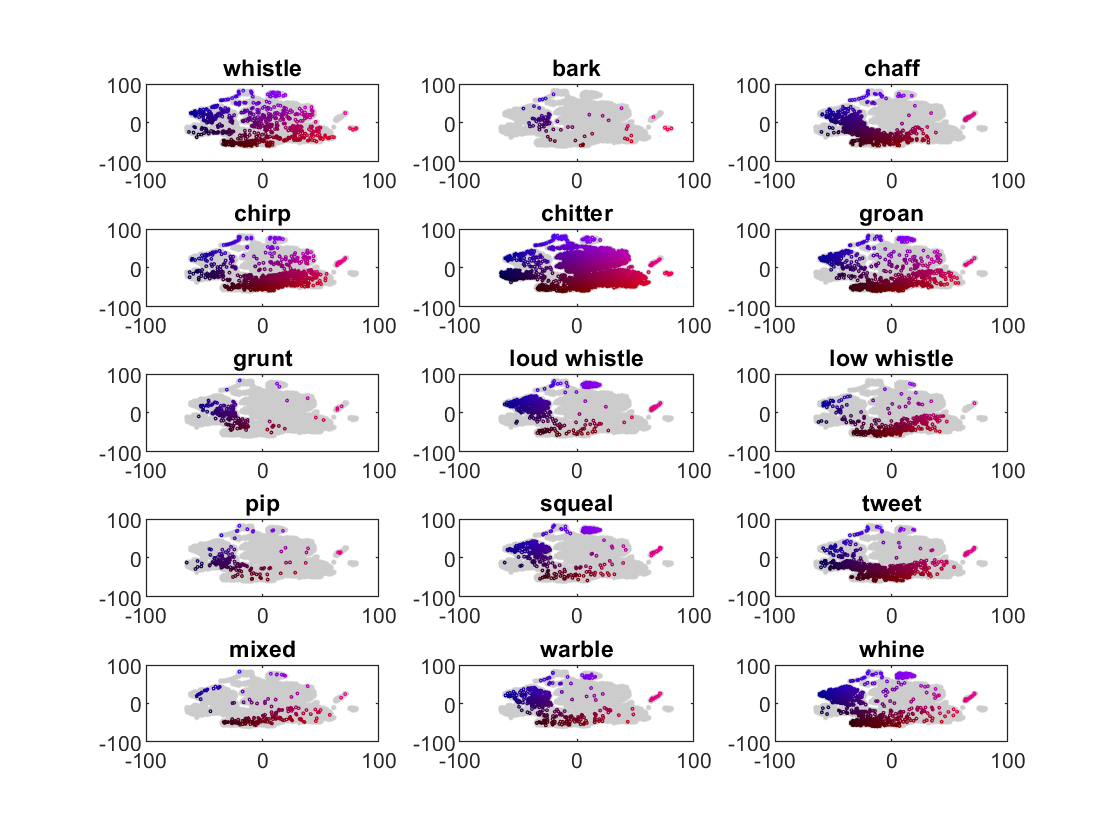

maxt = max(y);
mint = min(y);

allcolors = zeros(size(y,1), 3);
allcolors(:,1) = (y(:,1)-mint(1))/(maxt(1)-mint(1));
allcolors(:,3) = (y(:,2)-mint(2))/(maxt(2)-mint(2));

 figure
 for i = 1:length(indvocsgood)

     curid = find(identcodes_nn == uid((indvocsgood(i))));
     sp = subplot(5,3,i);
          plot(y(:,1), y(:,2), '.', 'Color', [.8 .8 .8]);
     hold on;     
     scatter(y(curid,1), y(curid, 2), 1, allcolors(curid,:));
     set(sp, 'YLim', [-100 100]);
     set(sp, 'XLim', [-100 100]);
     title(rdb.voctypes(indvocsgood(i)));
 end